## Program args

PlotData = true;

## 导入数据

运行前导航到该脚本所在目录

x=load("result\x.txt");
u=load('result\u.txt');
params = readtable("result\params.txt");
t=params.dt*(0:params.nsteps);
noise_type_str = ["No Noise", "BIT FLIP", "DEPOLARIZING", "DEPHASING", "DAMPING"];

导入的数据

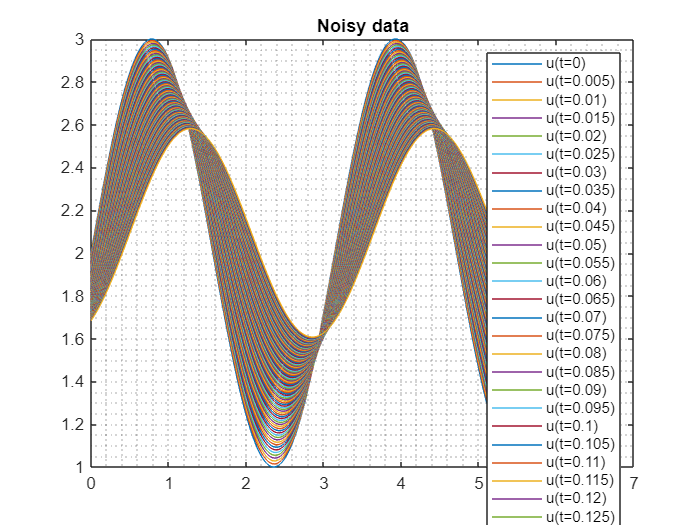

if PlotData
    figure;hold on;
    for i=0:params.nsteps
        ui=u(i+1,:);
        plot(x,ui, 'DisplayName',strcat('u(t=',num2str(params.dt*i),')'));
    end
    legend;
    box on;
    grid minor;
    title('Noisy data')
end

## 对采样进行平滑（Local quadratic regression）


smoothed = zeros(params.nsteps+1,2^params.nqubits);
for i=0:params.nsteps
    ui=u(i+1,:);

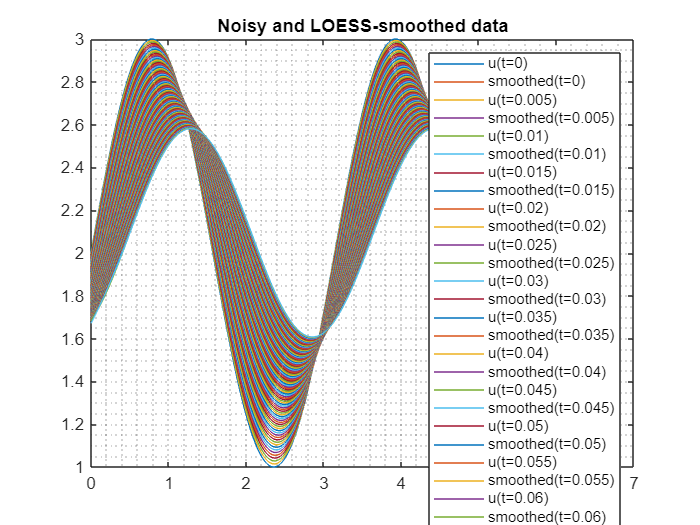

% Smooth input data
smoothed_ui = smoothdata(ui,"loess",1,"SamplePoints",x);
    smoothed(i+1,:)=smoothed_ui;    
    
end
if PlotData
    figure;hold on;
    for i=0:params.nsteps
        plot(x,u(i+1,:), 'DisplayName',strcat('u(t=',num2str(params.dt*i),')'));
        plot(x,smoothed_ui,'DisplayName',strcat('smoothed(t=',num2str(params.dt*i),')'));
    end
    legend;
    box on;
    grid minor;
    title('Noisy and LOESS-smoothed data')
end

## 用扩散型模型对采样进行拟合

### 对每个 t, 拟合 u

对每个时刻t，拟合模型$u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$

modelEq = '$\ u(x,t;D,E,F,G)=D\sin(E(x-Ft))+G$';
function v = diffusion_model(p,x,t,lambda)
    D=p(1);
    E=p(2);
    F=p(3);
    G=p(4);
    v = D*sin(E*(x-F*t))+G ;
end
% unused
function error = residual_u(p,x,u_observed,lambda,c,t)
    v_predicted = diffusion_model(p,x,lambda,c,t);
    error = sum((u_observed - v_predicted).^2);
end

优化求解

D_opt = zeros(params.nsteps,1);
E_opt = zeros(params.nsteps,1);
F_opt = zeros(params.nsteps,1);
G_opt = zeros(params.nsteps,1);
% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
resnorms = zeros(params.nsteps,1);
for i = 1:params.nsteps
    ui = u(i+1,:);
    % D E F G
    p_initial = [1.0, params.lambda, params.c,  params.offset];
    lb =        [0,   0,             0,         -Inf         ];
    ub =        [Inf, Inf,           2*pi,      Inf          ];
    options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
    [p_opt, resnorms(i)]=lsqcurvefit(@(p,x)diffusion_model(p,x,params.dt*(i),params.lambda), p_initial, x, ui, lb, ub, options);
    D_opt(i) = p_opt(1);
    E_opt(i) = p_opt(2);
    F_opt(i) = p_opt(3);
    G_opt(i) = p_opt(4);
end


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5         0.0316878                             2.68
     1         10       0.000235714       0.0113581           0.0274      
     2         15       0.000232658       0.0011291         5.27e-06      
     3         20       0.000232658     8.23454e-08         1.65e-09      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

                              

ModelArgs = table(D_opt,E_opt,F_opt,G_opt,resnorms)

ModelArgs = 100×5 table
     D_opt     E_opt      F_opt     G_opt      resnorms 
    _______    ______    _______    ______    __________

    0.98954         2    0.99353    2.0026    0.00023266
    0.97929         2    0.99468    2.0051    0.00086415
    0.96926         2    0.99569    2.0075     0.0018076
    0.95943         2    0.99665    2.0099     0.0029865
    0.94979         2     0.9976    2.0122     0.0043443
    0.94035         2    0.99848    2.0144     0.0058207
    0.93109         2    0.99931    2.0166     0.0073771
    0.92201         2     1.0001    2.0186     0.0089758
     0.9131         2     1.0009    2.0207      0.010587
    0.90436    2.0001     1.0016    2.0226      0.012185
    0.89578    2.0001     1.0023    2.0245      0.013748
    0.88735    2.0001     1.0029    2.0264      0.015264
    0.8

### 拟合 D-t 曲线

对每个时刻t，拟合模型$D(t)=Pe^{Qt}+R$

modelEq_D = '$\ D(t)=Pe^{Qt}+R$';
function v = D_model(p,t)
    P=p(1);
    Q=p(2);
    R=p(3);
    v = P*exp(Q*t)+R ;
end

function error = residual_D(p,t,D_observed)
    D_predicted = D_model(p,t);
    error = sum((D_observed-D_predicted).^2);
end

优化求解

% resnorm is the squared 2-norm of the residual(残差) at x: sum((fun(x,xdata)-ydata).^2).
%           [P    Q                 R    ]
p_initial = [1.0, -0.5, 0.1 ];
lb =        [0,   -Inf,             -Inf ];
ub =        [Inf, 0,                Inf  ];
options = optimoptions('lsqcurvefit', 'Display', 'iter', 'Algorithm','trust-region-reflective');
[p_opt, resnorm_D]=lsqcurvefit(@(p,t)D_model(p,t), p_initial, t(2:end)', D_opt, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          4           9.92484                             30.5
     1          8          0.065661        0.710673             1.55      
     2         12         0.0204524        0.215363            0.186      
     3         16         0.0204524        0.407751            0.186      
     4         20         0.0180452        0.101938           0.0692      
     5         24         0.0148827        0.203876            0.257      
     6         28         0.0148827        0.465778            0.257      
     7         32         0.0123273        0.101938           0.0599      
     8         36         0.0095744        0.203876            0.202      
     9         40        0.00875257        0.407751            0.632      
    10         44        0.00334744        0.101938           0.0403      
    11         48        0.00162223      

P=p_opt(1);
Q=p_opt(2);
R=p_opt(3);

单个时刻的解和模型

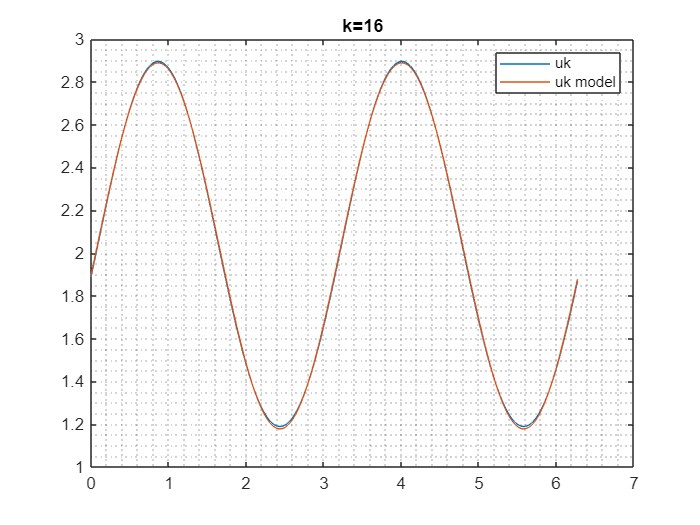

figure;hold on;
k=16;
u4=u(k+1,:);
u4model=diffusion_model([D_opt(k),E_opt(k),F_opt(k),G_opt(k)],x,params.dt*k, params.lambda);

plot(x,u4,'DisplayName','uk');
plot(x,u4model,'DisplayName','uk model');
%plot(x,smoothed(k+1,:),'DisplayName','smoothed k')

grid minor; box on;
legend;
title(strcat('k=',num2str(k)));

## 绘制参数曲线

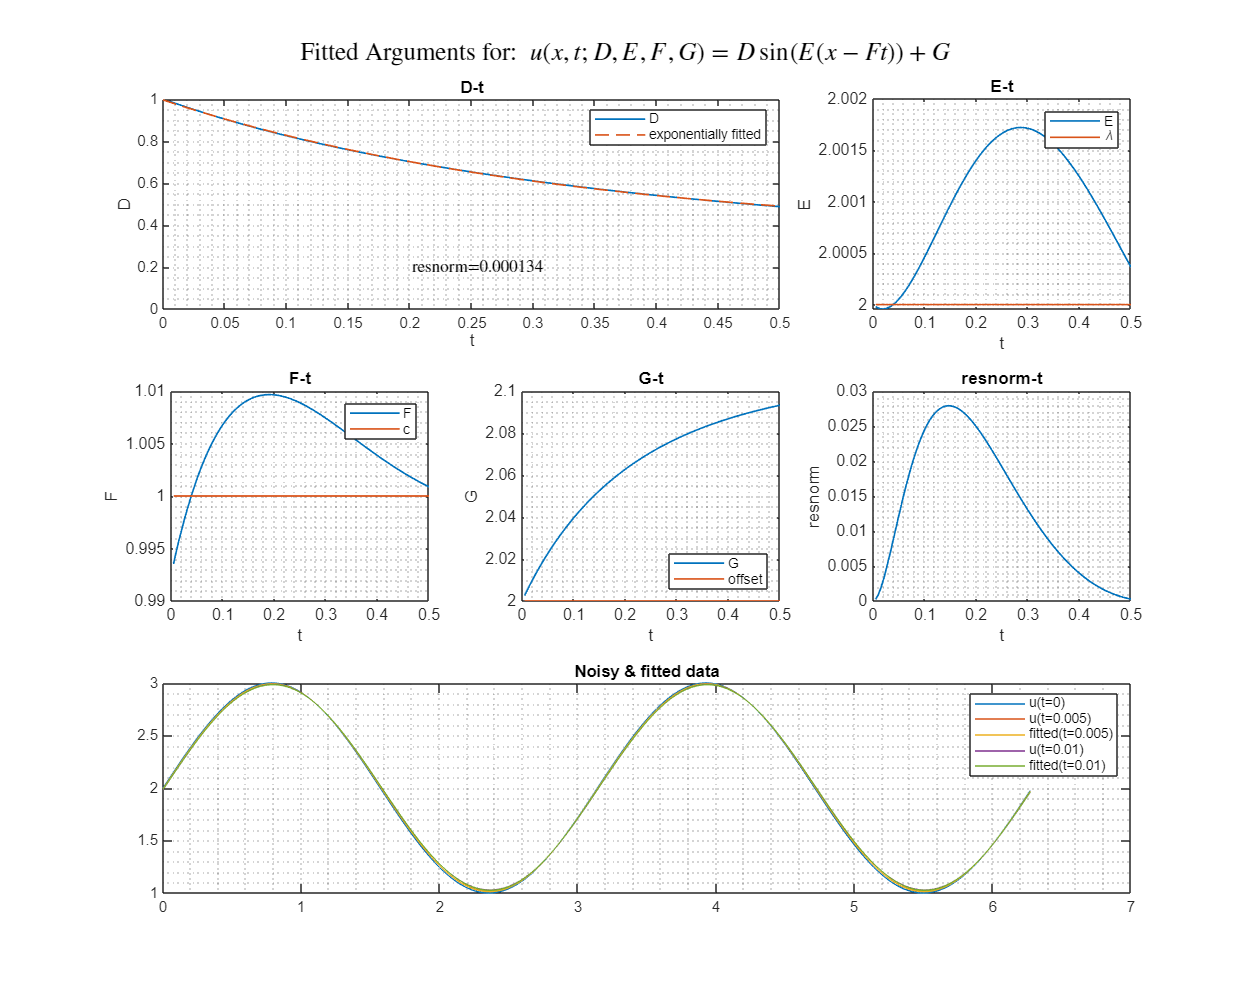

fig_args=figure(Position=[0,0,1280,1024]);
subplot(3,3,1:2);
hold on;
plot(t(2:end), D_opt, 'DisplayName','D','LineWidth',1.0);
plot(t,D_model(p_opt,t),'--', 'DisplayName','exponentially fitted', 'LineWidth', 1.0);
text(0.2,0.2,strcat('resnorm=', num2str(resnorm_D)),'Interpreter','latex');
box on; grid minor;
legend;
ylim([0 1]);

xlabel('t');
ylabel('D');
title('D-t')

subplot(3,3,3);
plot(t(2:end),E_opt(1:end),LineWidth=1,DisplayName='E');
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.lambda,DisplayName='\lambda',LineWidth=1);
legend;
xlabel('t');
ylabel('E');
title('E-t')
grid minor;

subplot(3,3,4);
plot(t(2:end),F_opt(1:end),LineWidth=1,DisplayName='F');
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.c,DisplayName='c',LineWidth=1);
legend;
xlabel('t');
ylabel('F');
title('F-t')
grid minor;

subplot(3,3,5);
plot(t(2:end),G_opt(1:end),LineWidth=1,DisplayName='G');
hold on;
plot(t(2:end),ones(1,length(t)-1)*params.offset,DisplayName='offset',LineWidth=1);
legend('location','southeast')
xlabel('t');
ylabel('G');
title('G-t')
grid minor;

subplot(3,3,6);
plot(t(2:end),resnorms(1:end),LineWidth=1);
xlabel('t');
ylabel('resnorm');
title('resnorm-t')
grid minor;

subplot(3,3,7:9);
hold on;
title('Noisy & fitted data');
% plot first 1/3 of the timespan for n_plot evenly_stepped times.
n_plot = 4;
step=floor(params.nsteps / n_plot / 2);
for i=0:2
    ui=u(i+1,:);
    plot(x,ui, 'DisplayName',strcat('u(t=',num2str(params.dt*i),')'));
    if i>0
        u_model = diffusion_model([D_opt(i),E_opt(i),F_opt(i),G_opt(i)],x, params.dt*(i), params.lambda);
        plot(x,u_model,'DisplayName',strcat('fitted(t=',num2str(params.dt*i),')'))
    end
end
grid minor; box on;
legend;

sgtitle(strcat('Fitted Arguments for: ',modelEq), Interpreter='latex')

### Save Figure

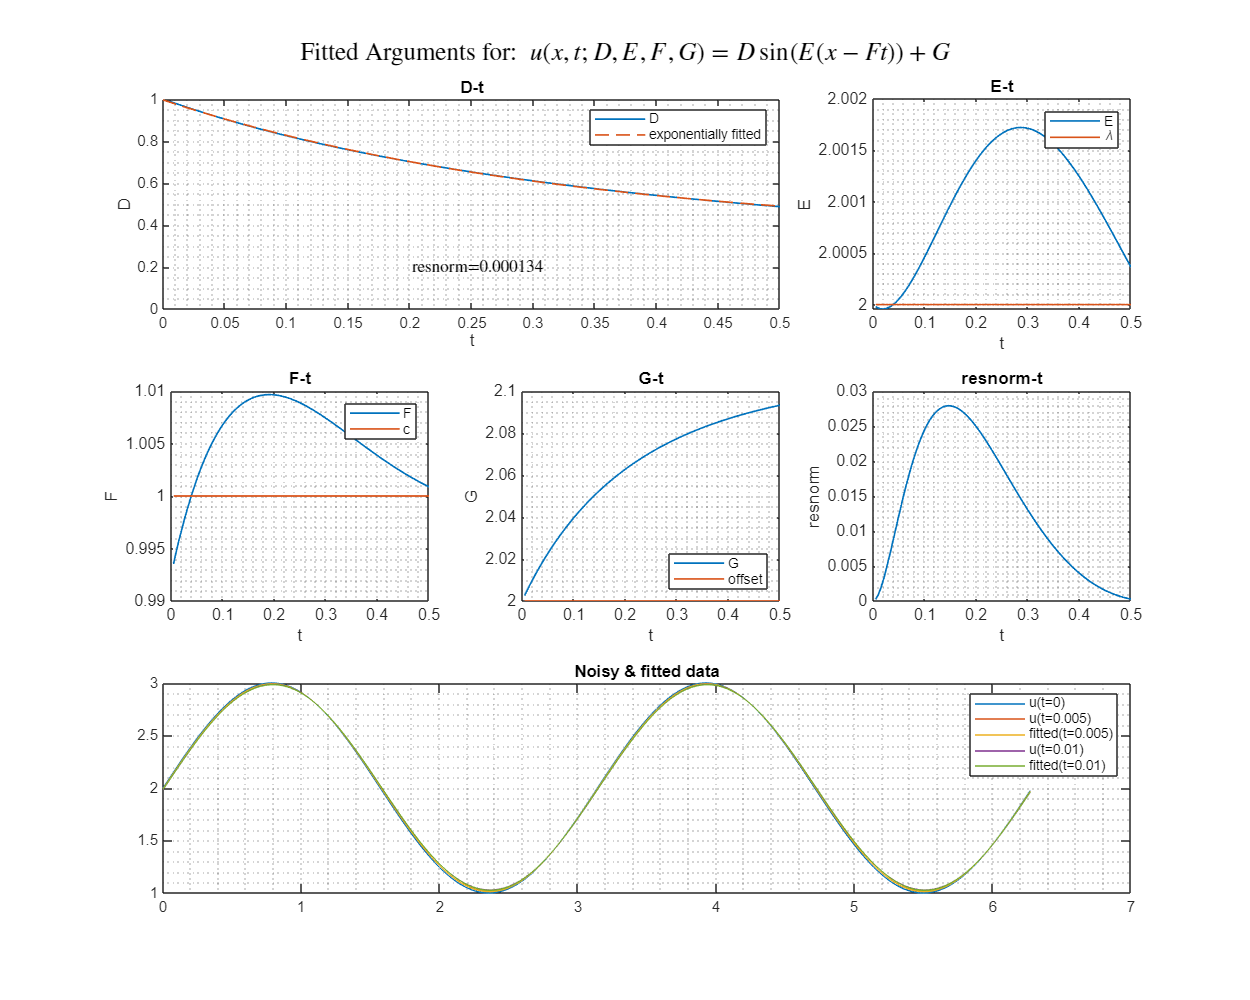

filename = strcat('result/',...
    noise_type_str(params.noise_type+1), num2str(params.noise_p),...
    '_lambda',num2str(params.lambda),...
    '_offset',num2str(params.offset),...
    '_dt', num2str(params.dt),...
    '_nqubits',num2str(params.nqubits));
savefig(fig_args, strcat(filename,'.fig'))
exportgraphics(fig_args, strcat(filename,'.pdf'));

## Save workspace

save(strcat(filename,'.mat'))


### Save modeling results

dlmwrite('result/ModelingResults.csv',...
    [params.c,params.L,params.lambda, params.offset, params.dt, params.nqubits, params.nsteps, params.noise_type, params.noise_p, P,Q,R,resnorm_D],...
    'delimiter',',','-append');

TODO: 只在大于0的部分拟合